clc;clear all;close all;
%syms x1 x2 u
%x=[x1;x2];
syms t
syms x [2 1]
syms u
f=sys(t,x,u);
%xeq=[3*pi/4;0]; %Punto de equilibrio
%ueq=0; %Entrada que sostiene equilibrio

%------------------------------------------
% Calculando el U deseado "ud"
syms ud 
xd =[pi; 0]; % X deseado
SS = solve(sys(t,xd,ud) == 0,ud);
ud = double(SS)

ud = 1.0812e-16

%------------------------------------------

Ajac=jacobian(f,x);
A=double(subs(Ajac,[x;u],[xd;ud]));
Bjac=jacobian(f,u);
B=double(subs(Bjac,[x;u],[xd;ud]));

eig(A)

ans =     3.1710
   -6.8747



x0=[-pi/3;0]; % Punto inicial
[T,X]=ode45(@(t,x)sys(t,x,controlPD(x,xd,ud)),[0:0.1:5],x0)

T =          0
    0.1000
    0.2000
    0.3000
    0.4000
    0.5000
    0.6000
    0.7000
    0.8000
    0.9000


X =    -1.0472         0
   -0.3429    6.9406
    0.2818    5.5986
    0.7860    4.5283
    1.1947    3.6794
    1.5279    3.0091
    1.8010    2.4746
    2.0261    2.0432
    2.2122    1.6920
    2.3666    1.4044


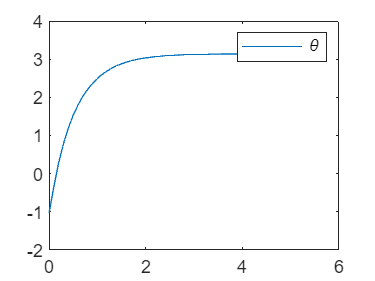

figure;
plot(T,X(:,1))
legend('\theta')


U=[]


U =

     []



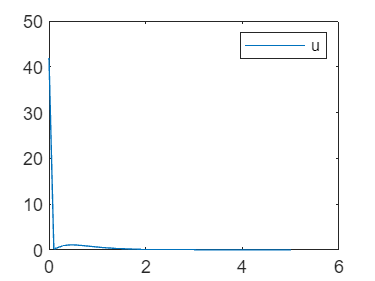

for i=1:length(T)
    U(i,1)=controlPD(X(i,:),xd,ud);
end
plot(T,U);
legend('u')

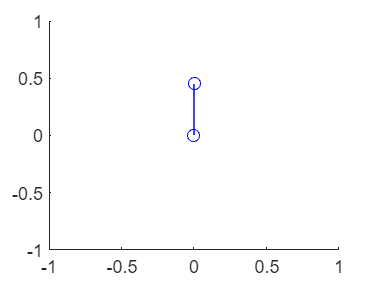

%Animacion
figure
h1=line;hold on;
l=0.45;
pause(2)
for i=1:length(T)
    th_i=X(i,1);
    delete(h1);
    h1=plot([0 l*sin(th_i)],[0 -l*cos(th_i)],'bo-');
    axis([-1 1 -1 1])
    drawnow
    pause(0.05);
end

function u=controlPD(x,xd,ud)
    %x1 posicion, x2 velocidad kp,kd
    %x1d=pi;x2d=0;
    kp=10;
    kd=5;
    %ud=0.62; %feedforward
    u=ud+kp*(xd(1,1)-x(1))+kd*(xd(2,1)-x(2));
end
function dx=sys(t,x,u)
    g=9.81;
    l=0.45;
    B=0.15;
    m=0.2;
    x1=x(1);x2=x(2);
    dx=[x2;
        -g/l*sin(x1)-B/(m*l^2)*x2+u/(m*l^2)];
end

